# P & PI Control

Open serial to Pico data port

clear s % closes ports already open
s = serialport('COM4',9600) % Check COM#

Send desired heigth and request for number of samples to Pico

desired_height = 10; 
s.writeline(num2str(desired_height)) % send desired height to Pico

samples = 700;
s.writeline(num2str(samples)) % send number of samples to Pico

height = zeros(1, samples); % create emply row vector for distance collection
voltage = zeros(1, samples); % create emply row vector for voltage collection

% loop for every sample
for i = 1:samples   
    height(i) = s.readline(); % receive distance from serial
    voltage(i) = s.readline(); % receive voltage from serial
end

save data_04_10_2024.mat height voltage

load data_04_10_2024.mat

plot(height, "b") % plot height

hold on
yline(10, "r", "LineWidth", 2) % plot desired height
hold off

%xlim([300 500])
%xlim([0 500])
axis([0 700 -5 30]) % set axis limits
title("Height (cm) vs. Sample Number Trial 1")
xlabel("Sample Number")
ylabel("Height (cm)") 
legend("Sensor Reading", "Desired Height")

plot(voltage, "b") % plot voltage

%xlim([300 500])
%xlim([0 500])
title("Voltage (V) vs. Sample Number Trial 1")
xlabel("Sample Number")
ylabel("Voltage (V)") 

Calculate linear fit parameters to find baseline voltages

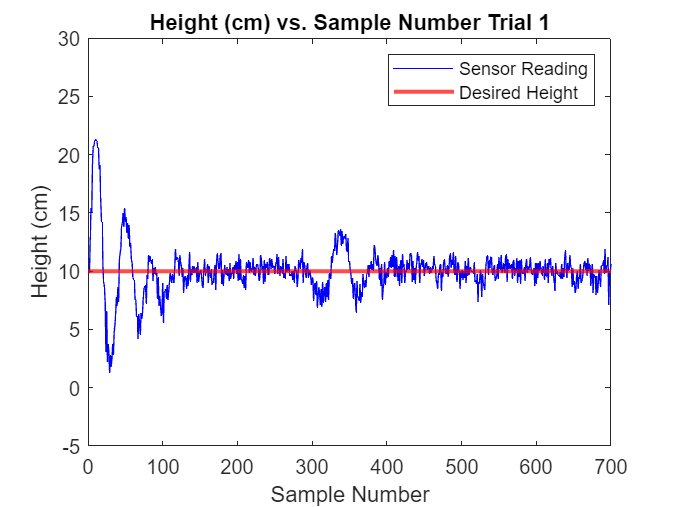

duty_cycle = [50 55 60 65 70 75]; % expiremented duty cycles
height = [3.352055 6.177309 8.201722 10.70005 15.25231 18.58077];

voltage = (duty_cycle ./ 100) .* 12; % convert duty_cycle to fan voltage

plot(height, voltage, 'bo') % plot data points

pfit = polyfit(height,voltage,1); % fit line to data 
pval = polyval(pfit, height); % evaluate fitted line

hold on
plot(height, pval, 'r') % plot fitted line
hold off

title("Voltage (V) vs. Height (cm)")
xlabel("Height (cm)")
ylabel("Voltage (V)")


% extract parameters
a = pfit(1)

a = 0.1950

b = pfit(2)

b = 5.4767